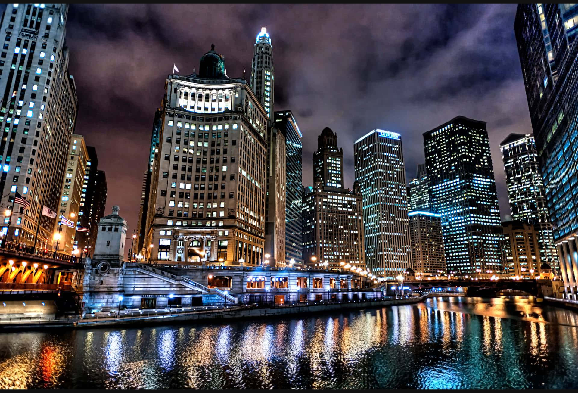

clear 
rgb = imread('city.jpg');

%rgb to grey scale
grey = gray_scale(rgb); 

horz3 = conv_hor_sobel(grey);
vert3 = conv_vert_sobel(grey);
edge = sqrt(double(vert3).^2 + double(horz3).^2);
edge = uint8(min(edge, 255));

edge_manh = abs(vert3) + abs(horz3);
edge_manh = uint8(min(edge_manh, 255));

% display results
imshow(rgb)

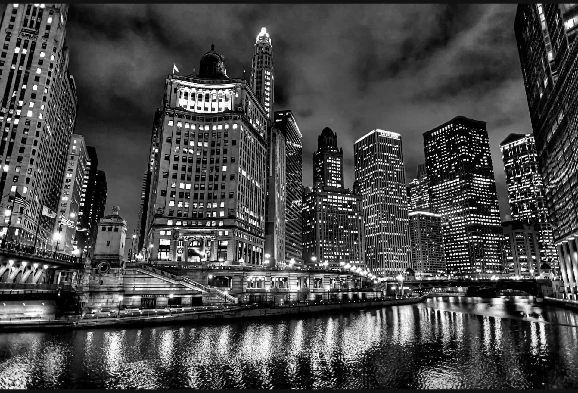

imshow(grey)

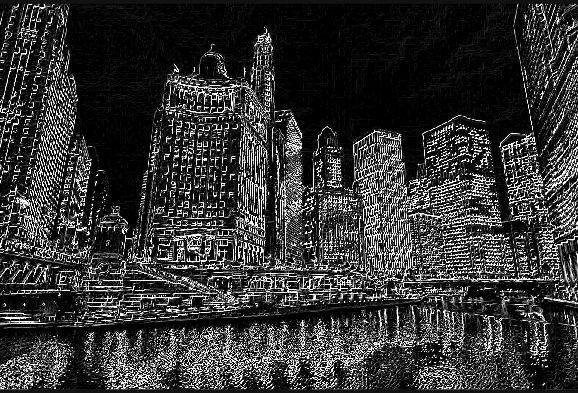

imshow(edge)

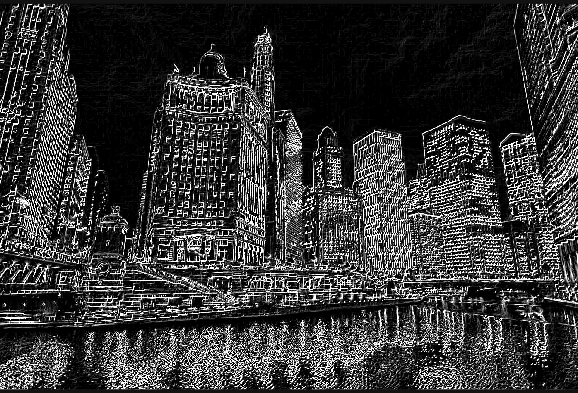

imshow(edge_manh)



function gray_img = gray_scale(rgb_img)
    red_channel = double(rgb_img(:,:,1));
    green_channel = double(rgb_img(:,:,2));
    blue_channel = double(rgb_img(:,:,3));
    gray_img = uint8(0.2989 * red_channel + 0.5870 * green_channel + 0.1140 * blue_channel);
end

function result = conv_hor_sobel(img)
    [img_height, img_width] = size(img);
    img_padded = padarray(img, [1, 1]);
    result = zeros(img_height, img_width);

    kernel = [1, 0, -1;
              2, 0, -2;
              1, 0, -1];

    for x = 1:img_height
        for y = 1:img_width
            region = double(img_padded(x:x+2, y:y+2));
            val = sum(sum(region .* kernel));
            result(x,y) = val;
        end
    end
    result = uint8(result);
end

function result = conv_vert_sobel(img)
    [img_height, img_width] = size(img);
    img_padded = padarray(img, [1, 1]);
    result = zeros(img_height, img_width);

    kernel = [1,  2,  1;
              0,  0,  0;
             -1, -2, -1];

    for x = 1:img_height
        for y = 1:img_width
            region = double(img_padded(x:x+2, y:y+2));
            val = sum(sum(region .* kernel));
            result(x,y) = val;
        end
    end
    result = uint8(result);
end